Playing heed_m.wav at 24000 Hz with duration 0.23 seconds and 5408 samples


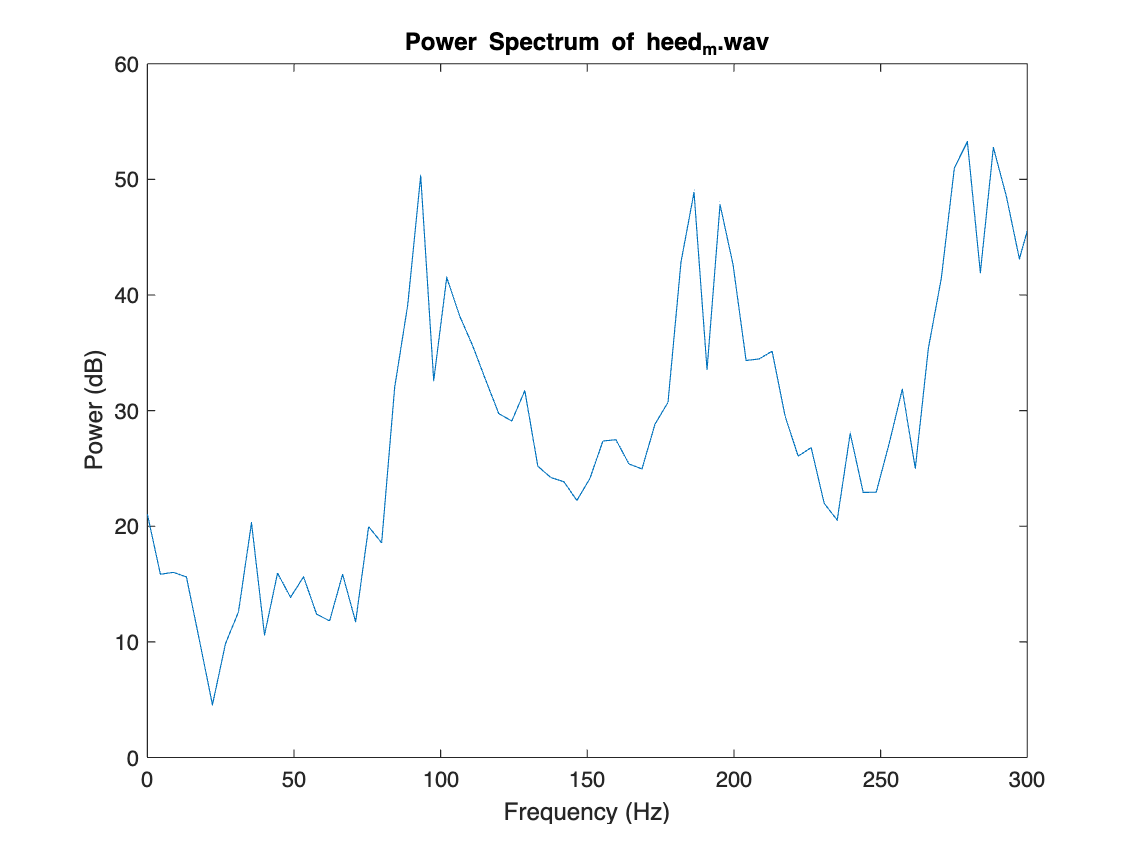

file_1 = 'heed_m.wav';
[audio, fs, duration, numSamples] = playAudio(file_1);

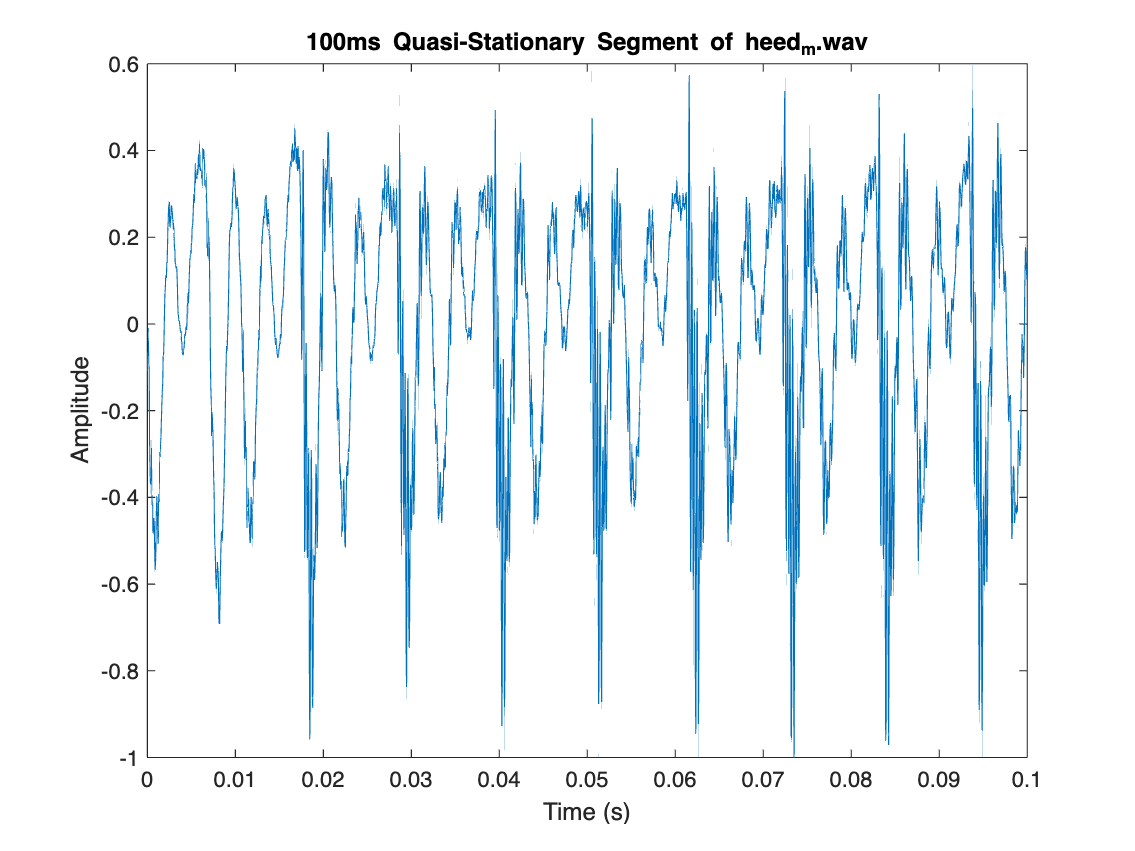

Window Size: 480 samples (20.00 ms)
Overlap: 360 samples (15.00 ms)
FFT Length (N): 2048

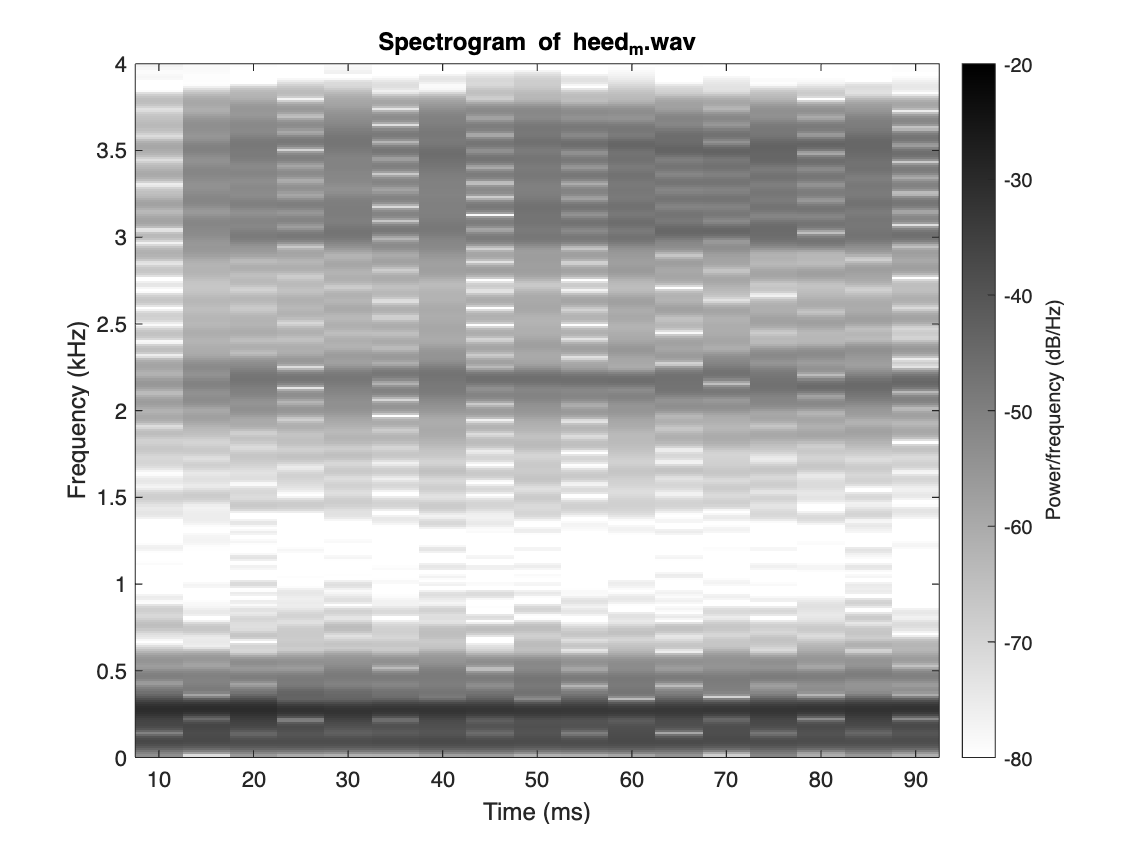

% select a 100ms quasi-stationary segment
segmentDuration = 0.1;
segment = extractCenterSegment(audio, fs, segmentDuration, file_1);
plotSpectrogram(segment, fs, file_1);

lpcCoeffs =     1.0000   -1.4665    0.6916   -0.1373    0.6399   -0.7553    0.0325   -0.2395    0.5534   -0.6850    0.7136   -0.5797   -0.0980   -0.0205    0.5620   -0.2063   -0.0164   -0.4652    0.8912   -0.3814    0.0293


g = 8.4176e-04

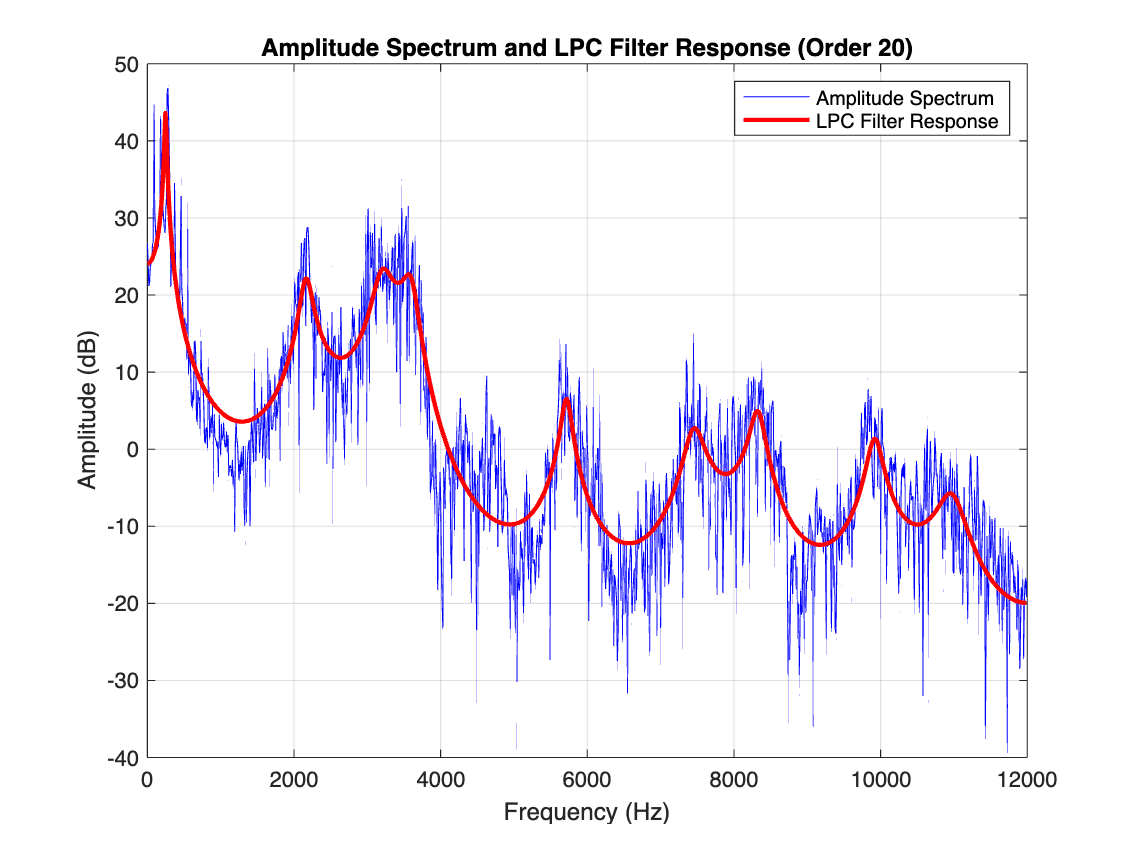

lpcOrder = 20;
plotLPCResponse(segment, fs, lpcOrder);

[formants] = estimateFormants(segment, fs, lpcOrder);

Estimated Formant Frequencies (Hz):
F1: 248.48 Hz
F2: 2163.34 Hz
F3: 3199.62 Hz


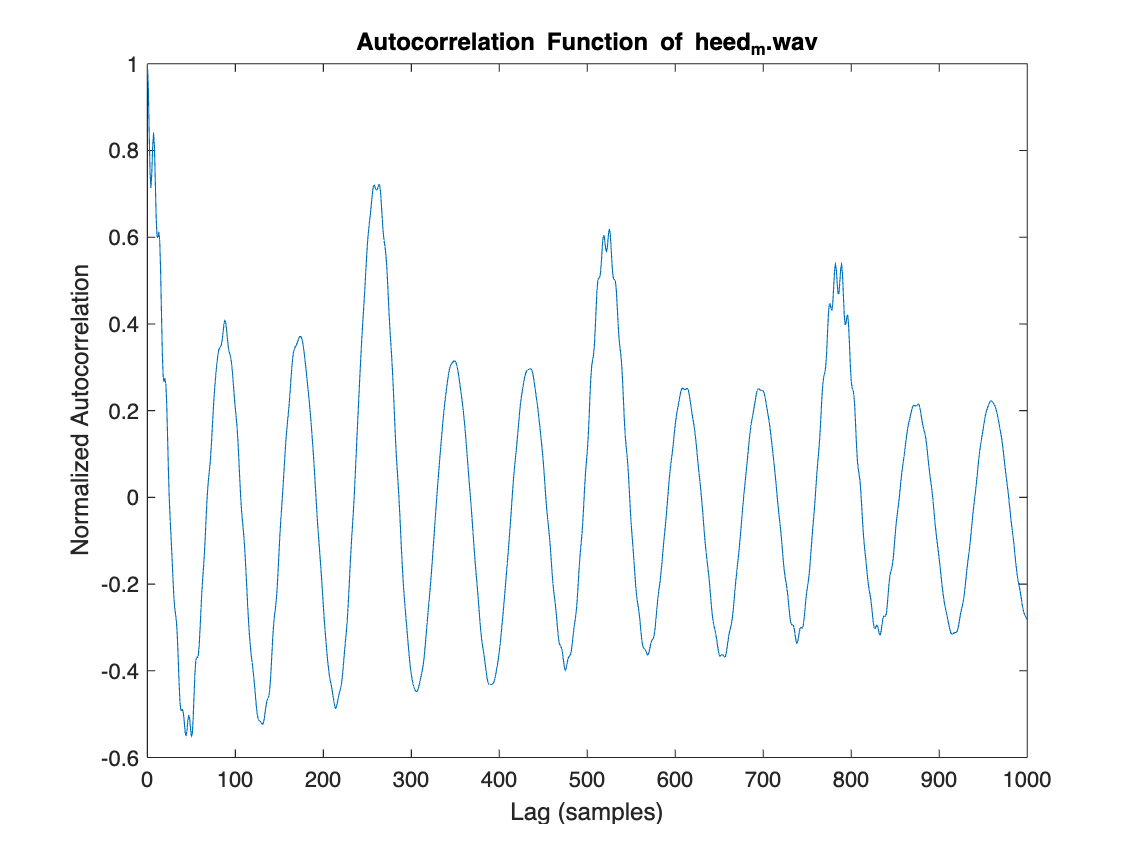

Estimated F0 using autocorrelation: 91.25 Hz


f0_estimate = estimateF0ByAutoCorrelation(segment, fs, file_1);

f0_power = estimateF0ByPowerSpectrum(segment, fs);

Estimated F0 using power spectrum: 90.00 Hz


f0 = mean(pitch(segment, fs));
fprintf('Estimated F0 using pitch function: %.2f Hz\n', f0);

Estimated F0 using pitch function: 90.91 Hz


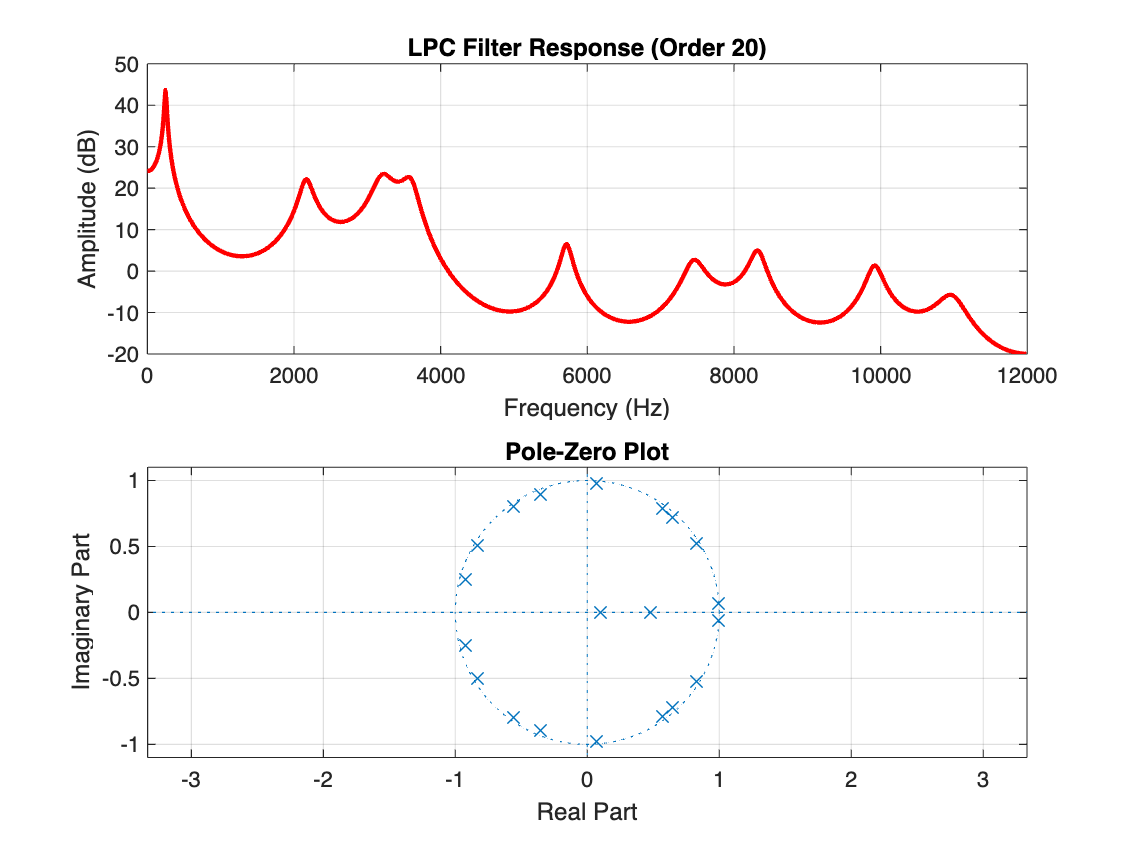

plotLPCPoleZero(segment, fs, lpcOrder);

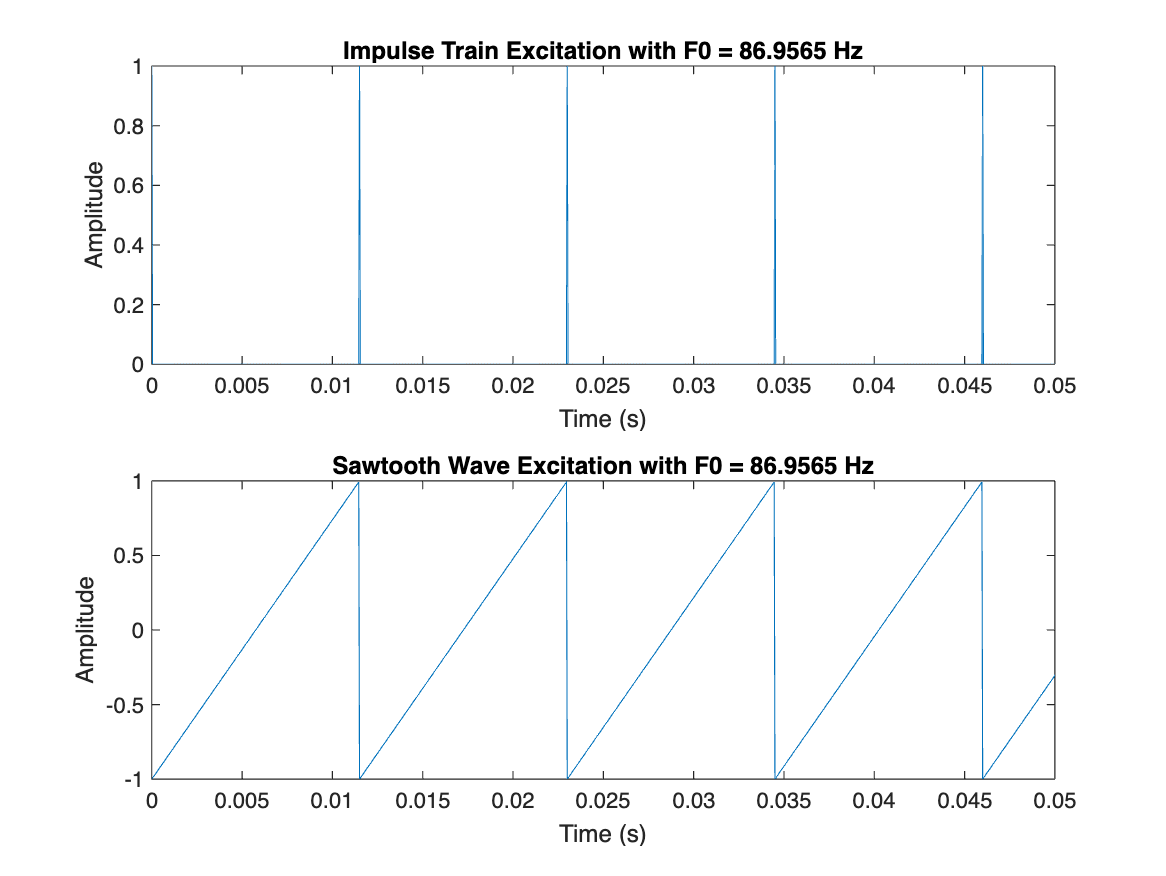

[synthesizedImpulse, synthesizedSawtooth] = synthesizeLPC(segment, fs, f0_estimate, lpcOrder, 1);

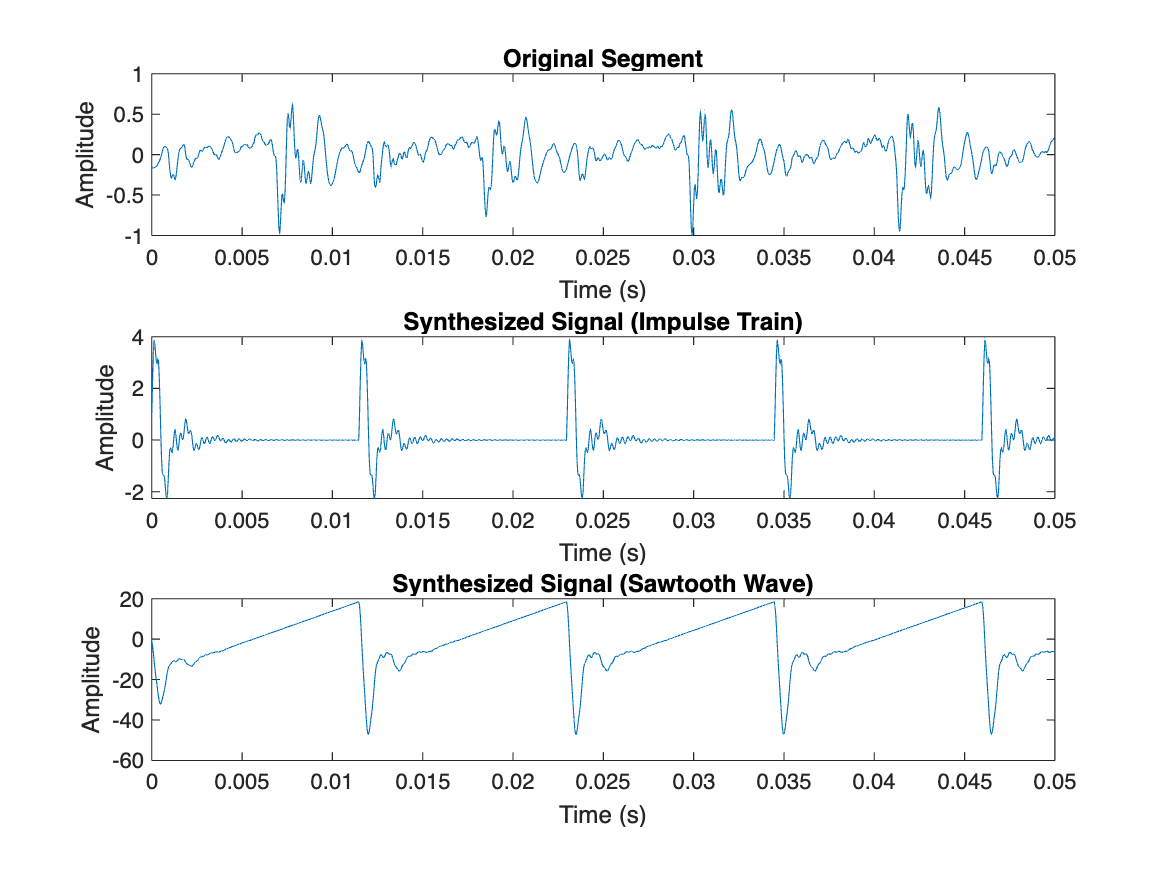

plotSynthesis(segment, fs, synthesizedImpulse, synthesizedSawtooth);